Load the data.

(given script)

loaddata

../Data/ACTOBS_S01_20161109_1108.mat
../Data/ACTOBS_S02_20161207-1002.mat
../Data/ACTOBS_S03_20161122-1529.mat
../Data/ACTOBS_S04_20161125-1211.mat
../Data/ACTOBS_S05_20161118_1339.mat
../Data/ACTOBS_S06_20161125-1033.mat
../Data/ACTOBS_S07_20161202-1521.mat
../Data/ACTOBS_S08_20161207-1434.mat
../Data/ACTOBS_S09_20161209-0958.mat
../Data/ACTOBS_S10_20161215-1615.mat
../Data/ACTOBS_S11_20161216-1131.mat
../Data/ACTOBS_S12_20161222-1036.mat
../Data/ACTOBS_S13_20161222-1406.mat
../Data/ACTOBS_S14_20170106-1517.mat
../Data/ACTOBS_S15_20170203-1237.mat


    flipped responses for block 1!


../Data/ACTOBS_S16_20170110-1509.mat
../Data/ACTOBS_S17_20170117-1048.mat
../Data/ACTOBS_S18_20170127-1459.mat
../Data/ACTOBS_S20_20170202-1235.mat
../Data/ACTOBS_S21_20170208-1404.mat
../Data/ACTOBS_S22_20170209-1228.mat
../Data/ACTOBS_S23_20170210-0956.mat
../Data/ACTOBS_S24_20170215-1430.mat
../Data/ACTOBS_S25_20170216-1146.mat
../Data/ACTOBS_S26_20170306-1121.mat
../Data/ACTOBS_S27_20170228-1126.mat
../Data/ACTOBS_S28_20170222-1442.mat
../Data/ACTOBS_S29_20170224-1500.mat
../Data/ACTOBS_S30_20170227-1227.mat
../Data/ACTOBS_S31_20170303-1217.mat
../Data/ACTOBS_S32_20170310-1222.mat
../Data/ACTOBS_S33_20170323-1400.mat
../Data/ACTOBS_S34_20170324-1142.mat
../Data/ACTOBS_S35_20170327-1331.mat
../Data/ACTOBS_S36_20170331-1156.mat
../Data/ACTOBS_S37_20170405-1006.mat
../Data/ACTOBS_S38_20170428-1701.mat


    flipped responses for block 3!


../Data/ACTOBS_S39_20170407-1250.mat
../Data/ACTOBS_S40_20170413-1019.mat
../Data/ACTOBS_S41_20170414-1217.mat
../Data/ACTOBS_S42_20170512-1659.mat
../Data/ACTOBS_S43_20170420-1010.mat


    flipped responses for block 3!


../Data/ACTOBS_S44_20170421-1000.mat
../Data/ACTOBS_S45_20170426-1613.mat
../Data/ACTOBS_S46_20170428-1010.mat
../Data/ACTOBS_S47_20170503-1206.mat
../Data/ACTOBS_S48_20170505-1619.mat
../Data/ACTOBS_S49_20170505-1459.mat


    flipped responses for block 4!


../Data/ACTOBS_S50_20170512-1014.mat
../Data/ACTOBS_S51_20170519-1218.mat
../Data/ACTOBS_S52_20170523-0945.mat
../Data/ACTOBS_S53_20170526-1234.mat
../Data/ACTOBS_S54_20170602-0957.mat
../Data/ACTOBS_S55_20170607-1243.mat
../Data/ACTOBS_S56_20170609-1512.mat
../Data/ACTOBS_S57_20170623-0958.mat
../Data/ACTOBS_S58_20170623-1507.mat
../Data/ACTOBS_S59_20170630-1425.mat
../Data/ACTOBS_S60_20170630-1230.mat
../Data/ACTOBS_S61_20170710-1045.mat
../Data/ACTOBS_S62_20170711-1605.mat
../Data/ACTOBS_S63_20170713-1206.mat
../Data/ACTOBS_S64_20170721-1024.mat
../Data/ACTOBS_S65_20170725-1611.mat
../Data/ACTOBS_S66_20170731-1328.mat
../Data/ACTOBS_S67_20170904-1326.mat
../Data/ACTOBS_S68_20170929-1722.mat
../Data/ACTOBS_S69_20170911-1111.mat
../Data/ACTOBS_S70_20170914-1002.mat
../Data/ACTOBS_S71_20170918-1305.mat
../Data/ACTOBS_S72_20170919-1123.mat
../Data/ACTOBS_S73_20170925-1300.mat
../Data/ACTOBS_S74_20170927-1335.mat
../Data/ACTOBS_S75_20171002-1207.mat
../Data/ACTOBS_S76_20171003-1445.mat
.

Inital fits ('nrep' number of fits) of the actual data to obtain an estimate of the two variables of interest, the probability of reversal (prev) and the choice probability (beta), that will serve fixed refence values to the next analyses.

nrep = 1e1;

dout = '../Out/'


clear prev_fit beta_fit
[prev_fit, beta_fit] = initialfit(nrep, nsubj, dat, subjlist);

prev_fix = mean(prev_fit(:))

prev_fix = 0.2087

beta_fix = mean(beta_fit(:))

beta_fix = 1.2439

Using a (given) function "sim_model_softmax", dataset are simulated using the fixed parameters (as the parameters are the same across the 2 tasks, we end up with 2*nsim simulated datasets).

nsim              = 500; % number of simulations
nsubjsubset       = [12 24 48 96] % number of participants (w/out consideration for condition, 96 = all)

nsubjsubset =     12    24    48    96




prev_recov_subjave = zeros(2*nsim, length(nsubjsubset));
beta_recov_subjave = zeros(2*nsim, length(nsubjsubset));
    
prev_diff_subjave = zeros(2*nsim,length(nsubjsubset));
beta_diff_subjave = zeros(2*nsim,length(nsubjsubset));

meansd_prev_diff_subjave = zeros(length(nsubjsubset),2);
meansd_beta_diff_subjave = zeros(length(nsubjsubset),2);

mean_corr_prev_beta = zeros(length(nsubjsubset),1)
shared_var          = zeros(length(nsubjsubset),1)


for isubjsubset = nsubjsubset

    prev_recov = zeros(isubjsubset,2,nsim);
    beta_recov = zeros(isubjsubset,2,nsim);
    
    
    
    isubjsubset
    seq_isubjsubsest = randperm(nsubj,isubjsubset)
    for isubj = seq_isubjsubsest
        for itask = 1:2
            
            % filter trials of interest
            ifilt = dat.subj == subjlist(isubj) & dat.task == itask;
            
            % simulate model
            cfg_sim        = [];
            cfg_sim.nsim   = nsim;
            cfg_sim.seqllr = dat.evid(ifilt);
            cfg_sim.seqind = dat.sind(ifilt);
            cfg_sim.prev   = prev_fix;
            cfg_sim.beta   = beta_fix;
            cfg_sim.brep   = 0; % force no repetition bias
            cfg_sim.epsi   = 0; % force no lapses
            
            out_sim        = sim_model_softmax(cfg_sim);
        

        Then each datasets is fit using the (given) function "fit_model_softmax".

            % fit simulated decisions
            for isim = 1:nsim
                cfg_fit        = [];
                cfg_fit.seqllr = out_sim.cfg.seqllr;
                cfg_fit.seqind = out_sim.cfg.seqind;
                cfg_fit.raft   = out_sim.raft(:,isim);
                cfg_fit.rbef   = out_sim.rbef(:,isim);
                cfg_fit.brep   = out_sim.cfg.brep; % force no repetition bias
                cfg_fit.epsi   = out_sim.cfg.epsi; % force no lapses
                    
                out_recov = fit_model_softmax(cfg_fit);
                

        Estimated value of prev and beta from each simulation are stored and their average value is computed.

                % store model parameters
                revindexsubj = find(seq_isubjsubsest==isubj);
                % isubj goes over the index limit --> reverse indexing with 
                % find(seq_isubjsubsest == isubj)
                prev_recov(revindexsubj,itask,isim) = out_recov.prev;
                beta_recov(revindexsubj,itask,isim) = out_recov.beta;
            end    
        end
    end

        Histogram of the recovered parameters and their difference from the fix one.

    revindexsubset = find(nsubjsubset==isubjsubset);
       
%     prev_recov_totave(:,revindexsubset)  = mean(prev_recov(:)); TO KEEP?
%     beta_recov_totave(:,revindexsubset)  = mean(beta_recov(:));
    
    prev_recov_cattask = squeeze(cat(3,prev_recov(:,1,:),prev_recov(:,2,:)))';
    beta_recov_cattask = squeeze(cat(3,beta_recov(:,1,:),beta_recov(:,2,:)))';
    
    prev_recov_subjave(:,revindexsubset) = mean(prev_recov_cattask,2);
    beta_recov_subjave(:,revindexsubset) = mean(beta_recov_cattask,2);
    
    figure;
    hold on
    title(["Probability of reversal (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(prev_recov_subjave(:,revindexsubset));
    hold off
    
    figure;
    hold on
    title(["Choice probability (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(beta_recov_subjave(:,revindexsubset));
    hold off
   
    
    prev_diff = prev_recov - prev_fix;
    beta_diff = beta_recov - beta_fix;
    
%     prev_diff_totave(:,revindexsubset)  = mean(prev_diff(:)); TO KEEP?
%     beta_diff_totave(:,revindexsubset)  = mean(beta_diff(:));
    
    prev_diff_cattask = squeeze(cat(3, prev_diff(:, 1, :), prev_diff(:,2,:)))';
    beta_diff_cattask = squeeze(cat(3, beta_diff(:, 1, :), beta_diff(:,2,:)))';
    

            Parameters for each stimulation (average across subjects) is stored outside the loop.

    
    prev_diff_subjave(:,revindexsubset) = mean(prev_diff_cattask, 2);
    beta_diff_subjave(:,revindexsubset) = mean(beta_diff_cattask, 2);
       
    figure;
    hold on
    title(["Difference recovered-fixed probability of reversal (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(prev_diff_subjave(:,revindexsubset));
    hold off
    
    figure;
    hold on
    title(["Difference recovered-fixed choice probability (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(beta_diff_subjave(:,revindexsubset));
    hold off

       Mean & variance of the distribution of recovered parameters across simulations for each subset of participants

    meansd_prev_diff_subjave(revindexsubset,1) = mean(prev_diff_subjave(:,revindexsubset));
    meansd_prev_diff_subjave(revindexsubset,2) = std(prev_diff_subjave(:,revindexsubset));
    
    meansd_beta_diff_subjave(revindexsubset,1) = mean(beta_diff_subjave(:,revindexsubset));
    meansd_beta_diff_subjave(revindexsubset,2) = std(beta_diff_subjave(:,revindexsubset));

        Correlation between the two parameters between subject is computed for each simulation.  

isubjsubset = 12

seq_isubjsubsest =     85    63    27     9    71    32    96    95    79    60    65    80


corr_prev_beta =     0.6888    0.3035    0.7023    0.4316   -0.2120    0.0263    0.4102    0.6877    0.7835    0.8240   -0.0365    0.2352    0.2109    0.3973    0.5779    0.5521    0.1258    0.5061    0.4488    0.4138   -0.1027    0.0805    0.6907    0.4221    0.2208   -0.0273    0.2945    0.4949    0.1260    0.5738    0.7691    0.5228    0.1646    0.4163    0.6815    0.3305    0.3157    0.6490    0.4825    0.4909    0.2913    0.2530    0.0242   -0.1959    0.1980    0.1213    0.4323    0.7867    0.6399    0.4333


mean_corr_prev_beta = 0.3487

shared_var = 0.1216

isubjsubset = 24

seq_isubjsubsest =     84    91    34    43     2    86    29    71    52    77    96    38    15     9    74    63    18    25    19    80    62    10     4    65


corr_prev_beta =     0.3730    0.2547    0.4455    0.3489    0.7270    0.6153    0.2703    0.3063    0.1703    0.2175    0.2224    0.5957    0.5015    0.1724    0.4807    0.4837    0.1530    0.1123    0.2599    0.5532    0.8211    0.2373    0.4488    0.0819    0.3397    0.5660    0.5678    0.3787    0.1131    0.4709    0.2694    0.4704    0.5286    0.2977    0.4048    0.3825    0.4047    0.4147    0.3261    0.4072    0.3066    0.1016    0.3570    0.3707    0.6354    0.4684    0.4631    0.3878    0.3765    0.7724


mean_corr_prev_beta =     0.3487    0.3495


shared_var =     0.1216    0.1221


isubjsubset = 48

seq_isubjsubsest =     47    88    45    20    81    63     3    52    67    96    64    29     8    61    56    40    27    83    50    70    26    75    85    68    23    84    19    49    77    53    31    30     1    93    78    17    90    66    10    79    73    51    34    18    59    36    15    25


corr_prev_beta =     0.3669    0.3371    0.4590    0.6197    0.3414    0.2754    0.5485    0.1335    0.3092    0.2131    0.5338    0.3232    0.5873    0.3696    0.4522    0.5720    0.2217    0.0831    0.3327    0.4638    0.5516    0.2385    0.3712    0.2683    0.3437    0.0911    0.1484    0.4086    0.3669    0.2312    0.7944    0.2739    0.3481    0.4115    0.1069    0.4514    0.3349    0.6046    0.3658    0.5672    0.1568    0.3581    0.5561    0.2488    0.3139    0.2672    0.4239    0.4539    0.3871    0.4207


mean_corr_prev_beta =     0.3487    0.3495    0.3611


shared_var =     0.1216    0.1221    0.1304


isubjsubset = 96

seq_isubjsubsest =     51    80    38    56    63    92    68     1    21    88    41    26    87    25    79    84    15    11    20    24    31     7    42     4    73    57    91    64    74    45    40    48    10    13    93    50     9    44    35    49    14    55    69    89    16    62    47    18    43    72


corr_prev_beta =     0.4820    0.2754    0.3515    0.4047    0.1403    0.3959    0.3838    0.3354    0.3866    0.2815    0.4748    0.3442    0.2546    0.3735    0.4475    0.3729    0.3124    0.5100    0.2297    0.4064    0.3114    0.3340    0.2389    0.3461    0.2410    0.2906    0.3184    0.4030    0.1869    0.4265    0.3494    0.3205    0.3870    0.2136    0.2837    0.3791    0.4203    0.4764    0.3722    0.4171    0.5467    0.4535    0.3347    0.4410    0.2228    0.3521    0.2618    0.2801    0.3944    0.0847


mean_corr_prev_beta =     0.3487    0.3495    0.3611    0.3517


shared_var =     0.1216    0.1221    0.1304    0.1237


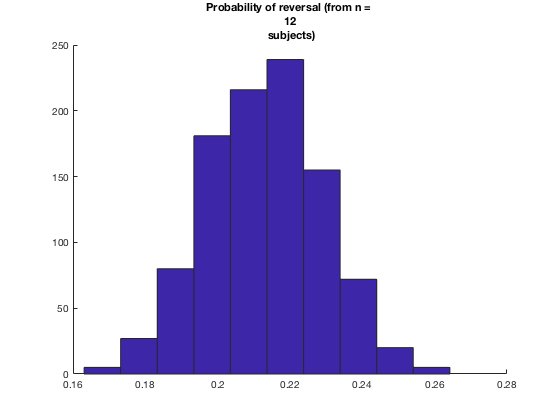

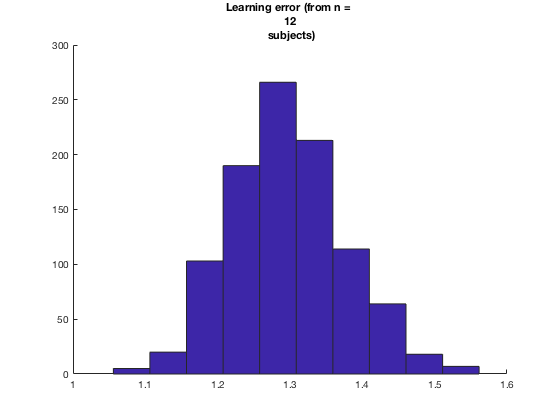

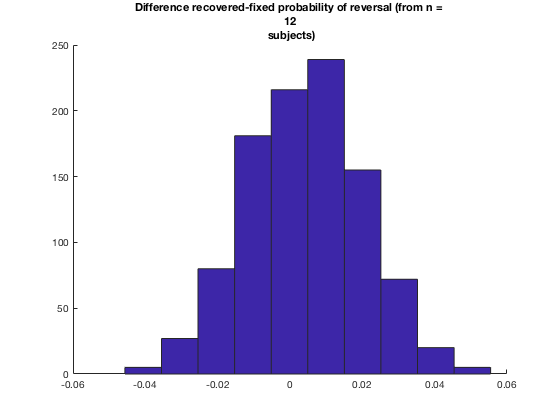

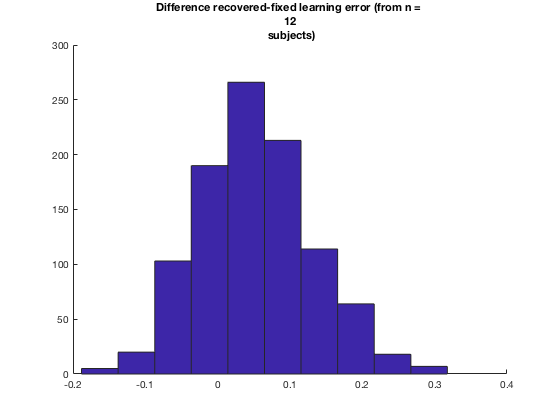

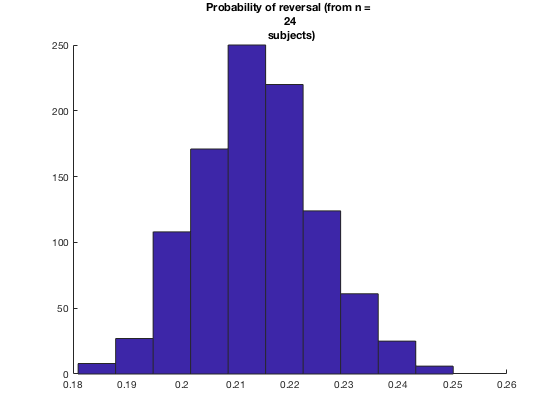

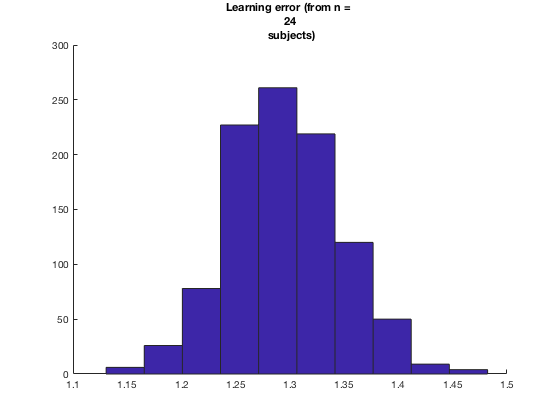

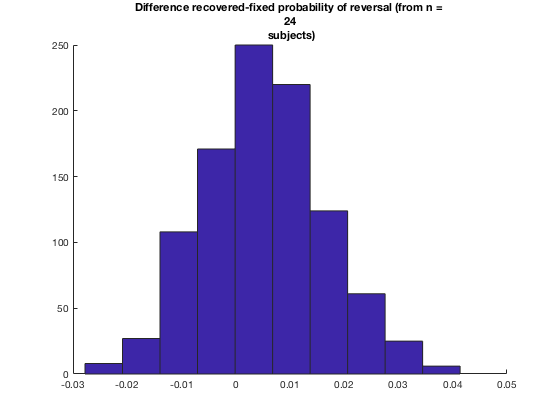

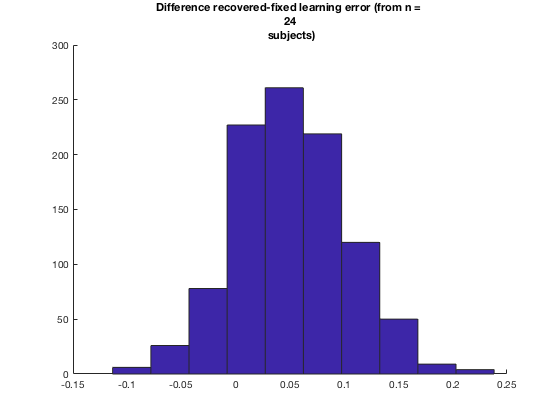

    prev_recov_cattask = squeeze(cat(3,prev_recov(:,1,:),prev_recov(:,2,:)));
    beta_recov_cattask = squeeze(cat(3,beta_recov(:,1,:),beta_recov(:,2,:)));
    
    corr_prev_beta = zeros(2*nsim)
    for isim = 1:2*nsim
        corr_prev_beta(isim) = corr(prev_recov_cattask(:,isim), beta_recov_cattask(:,isim));
    end
    corr_prev_beta
    mean_corr_prev_beta(:,revindexsubset) = mean(corr_prev_beta)
    shared_var(:,revindexsubset)          = mean_corr_prev_beta(:,revindexsubset)^2
    
end

Saving data of interest

dout = '../Out/' % folder for produced data

dout = '../Out/'


str_nsubjsubset = '';
for isubjsubset = nsubjsubset
    str_nsubjsubset = [str_nsubjsubset, num2str(isubjsubset),'-'];
end
str_nsubjsubset = str_nsubjsubset(1:end-1) % to delete the last useless '-'

str_nsubjsubset = '12-24-48-96'

    
formatSpec_file = '%s%s_%dsim_%ssubj%s';
    
name_file = sprintf(formatSpec_file, dout,'prev_recov',nsim,str_nsubjsubset,'.mat');
save(name_file, 'nsim','prev_fix','prev_recov_subjave','prev_diff_subjave',    ...
                'meansd_prev_diff_subjave','mean_corr_prev_beta','shared_var')

Error using save
Variable 'meansd_prev_diff_subjave' not found.


name_file = sprintf(formatSpec_file, dout,'beta_recov',nsim,str_nsubjsubset,'.mat');
save(name_file, 'nsim','beta_fix','beta_recov_subjave','beta_diff_subjave',    ...
                'meansd_beta_diff_subjave','mean_corr_prev_beta','shared_var')

Histogram of the paramterer according the number of subject they were estimated from (n = 12, 24, 48 or 96).

finalplots(dout, nsubjsubset, nsim, str_nsubjsubset, formatSpec_file, ...
           prev_diff_subjave, 'probability of reversal', 'prev')

finalplots(dout, nsubjsubset, nsim, str_nsubjsubset, formatSpec_file, ...
           beta_diff_subjave, 'choice variability', 'beta')